# Decentralized approach

rng('default');
clear;

## Settings

addpath('utils/visualization/');
addpath('utils/colors');
addpath('utils/settings');

make_settings("DataType", "condo", "PriceType", "enel")
load('settings.mat');
load('colors.mat');

plotter = Plotter(T);

#### Power generation and demand

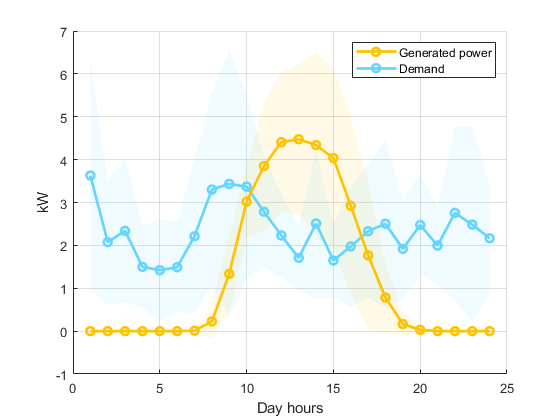

plotter.doublePlot(avg_PV, std_PV, avg_DP, std_DP, 2, 2, "-o", "-o", ...
                   colors.generation, colors.demand, ...
                   "Day hours", "kW", "Generated power", "Demand");

## Optimization problem

### Settings

ITER   = 150;         % Number of iteration
lambda = zeros(1,T);  % Lagrange multipliers [D_up - Q_down]
psi    = zeros(1,T);  % Lagrange multipliers [D_down - Q_up]
chi    = 1e-2;        % Convergence coefficient
ro     = 0.1;
gamma  = 1;

options = optimset('Display', 'off'); 

prosumer_time = zeros(1, P*ITER);
provider_time = zeros(1, S*ITER);

### History

hist.prov_cost     = zeros(ITER, S); % Providers cost function
hist.pros_cost     = zeros(ITER, P); % Prosumers cost function
hist.constr_lambda = zeros(ITER, T); % Constraints value 
hist.constr_psi    = zeros(ITER, T); % Constraints value 
hist.pros_x        = zeros(P, 5*T);  % Prosumer variables
hist.prov_x        = zeros(S, 3*T);  % Provider variables

### Algorithm

#### Prosumers problem

Invariant terms of the *prosumers* problem

% (Prosumers) Equality constraints matrix
K_P = -eye(T) + diag(alpha*ones(1,T-1),-1);
k_P = [zeros(1, T-1) 1];

pros_A = [eye(T) -eye(T) eye(T) -eye(T) zeros(T);
          zeros(T) zeros(T) -Eff_dis*eye(T) Eff_ch*eye(T) K_P;
          zeros(1,T) zeros(1,T) zeros(1,T) zeros(1,T) k_P];

% (Prosumers) Inquality constraints matrix
pros_B = kron([1 0 0 0 0; 
               0 1 0 0 0; 
               0 0 1 0 0; 
               0 0 0 1 0], eye(T));

% (Prosumers) Inquality constraints vector
pros_b = [ones(2*T,1) * p_max;
          ones(2*T,1) * d_max];

% (Prosumers) Lower bound vector
pros_l = zeros(1, 5*T);

#### Providers problem

Invariant terms of the *providers* problem

% (Providers) Equality constraint matrix
K_S = -eye(T) + diag(alpha*ones(1,T-1),-1);
prov_A = [Eff_ch*eye(T) -Eff_dis*eye(T) K_S];

% (Providers) Lower bound vector
prov_l = zeros(1, 3*T);

#### Iterative process

for k=1:ITER
    
    q_up   = zeros(S, T); % (Provider)
    q_down = zeros(S, T); % (Provider) 
    d_up   = zeros(P, T); % (Prosumer)
    d_down = zeros(P, T); % (Prosumer)
    
    prev_q_up   = zeros(S, T); % (Provider, prev. iter.)
    prev_q_down = zeros(S, T); % (Provider, prev. iter.)
    prev_d_up   = zeros(P, T); % (Prosumer, prev. iter.) 
    prev_d_down = zeros(P, T); % (Prosumer, prev. iter.) 
    
    % Prosumers loop
    for i=1:P
        start_prosumer_time = tic();
        
        % (Prosumers) Objective function matrix
        pros_H = diag([csi(i)*ones(1,T) csi(i)*ones(1,T) (csi(i) + ro)*ones(1,T) (csi(i) + ro)*ones(1,T) zeros(1,T)]);
        
        % (Prosumers) Objective function vector
        pros_f = [C -R lambda-ro*prev_d_up(i,:) psi-ro*prev_d_down(i,:) L];
        
        % (Prosumers) Equality constraints vector
        pros_a = [DP(i,:)' - PV(i,:)'; 
                  -alpha * s_init(i);
                  zeros(T-1,1);
                  s_init(i)];
        
        % (Prosumers) Solve the problem for the i-th prosumer
        [pros_x, pros_cost] = quadprog(pros_H, pros_f, pros_B, pros_b, pros_A, pros_a, pros_l, [], [], options);
        
        % (Prosumers) Update charge and discharge
        d_up(i,:)   = pros_x(2*T+1 : 2*T+T);
        d_down(i,:) = pros_x(3*T+1 : 3*T+T);
        
        % (Prosumers) Update history
        hist.pros_cost(k, i) = pros_cost;
        hist.pros_x(i, :)    = pros_x;
        
        prosumer_time(P*k + i) = toc(start_prosumer_time);
    end
    
    % Providers loop
    for j=1:S
        start_provider_time = tic();
        
        % (Providers) Objective function matrix 
        prov_H = kron([zeta(j)+ro zeta(j) 0;
                       zeta(j) zeta(j)+ro 0;
                       0 0 0], eye(T));

        % (Providers) Objective function vector
        prov_f = [-psi-ro*prev_q_up(j,:) -lambda-ro*prev_q_down(j,:) -L];

        % (Providers) Equality constraint vector
        prov_a = [-alpha*b_init(j);
                  zeros(T-1,1)];
        
        % (Providers) Upper bound
        prov_u = [ones(2*T,1) * q_max;
                  ones(T,1) * b_max(j)];
        
        % (Providers) Solve the problem for the j-th provider
        [prov_x, prov_cost] = quadprog(prov_H, prov_f, [], [], prov_A, prov_a, prov_l, prov_u, [], options);
        
        % (Providers) Update battery level
        q_up(j,:)   = prov_x(1 : T);
        q_down(j,:) = prov_x(T+1 : T+T);
        
        % (Providers) Update history
        hist.prov_cost(k, j) = prov_cost;
        hist.prov_x(j, :)    = prov_x;
        
        provider_time(S*k + j) = toc(start_provider_time);
    end
   
    Q_up   = gamma*sum(q_up, 1) + (1 - gamma)*sum(prev_q_up, 1); 
    Q_down = gamma*sum(q_down, 1) + (1 - gamma)*sum(prev_q_down, 1); 
    D_up   = gamma*sum(d_up, 1) + (1 - gamma)*sum(prev_d_up, 1);
    D_down = gamma*sum(d_down, 1) + (1 - gamma)*sum(prev_d_down, 1);
    
    prev_d_up   = d_up;
    prev_d_down = d_down;
    prev_q_up   = q_up;
    prev_q_down = q_down;
    
    constr_lambda = D_up - Q_down;
    constr_psi    = D_down - Q_up;
    
    lambda = lambda + chi.*constr_lambda;
    psi    = psi + chi.*constr_psi;
    hist.constr_lambda(k,:) = constr_lambda;
    hist.constr_psi(k,:)    = constr_psi;
end

prosumer_mean_elapsed_time = mean(prosumer_time)

prosumer_mean_elapsed_time = 0.0070

provider_mean_elapsed_time = mean(provider_time)

provider_mean_elapsed_time = 0.0023

## Results

### Gathering variables

% Prosumers variables
noncoop.var.p_up   = hist.pros_x(:,1:T);
noncoop.var.p_down = hist.pros_x(:,T+1:2*T);
noncoop.var.d_up   = hist.pros_x(:,2*T+1:3*T);
noncoop.var.d_down = hist.pros_x(:,3*T+1:4*T);
noncoop.var.s      = hist.pros_x(:,4*T+1:5*T);

% Providers variables
noncoop.var.q_up   = hist.prov_x(:,1:T);
noncoop.var.q_down = hist.prov_x(:,T+1:2*T);
noncoop.var.b      = hist.prov_x(:,2*T+1:3*T);

### Gathering parameters

noncoop.par.L = L;
noncoop.par.C = C;
noncoop.par.R = R;
noncoop.par.zeta = zeta;
noncoop.par.csi = csi;

### Lagrangian multiplier convergence

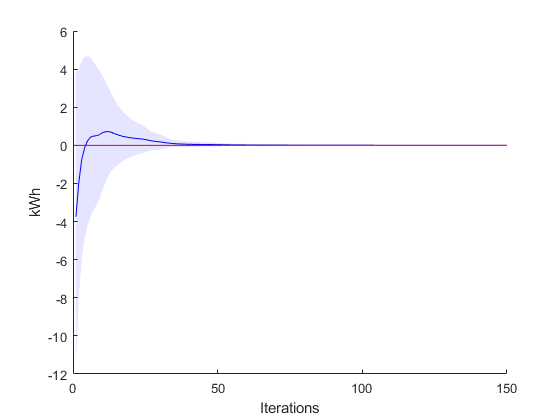

constr = [hist.constr_lambda hist.constr_psi];

avg_constr = mean(constr, 2)';
std_constr = std(constr, 0, 2)';

plotter.plotConvergence(avg_constr, std_constr, ITER);

### Power bought

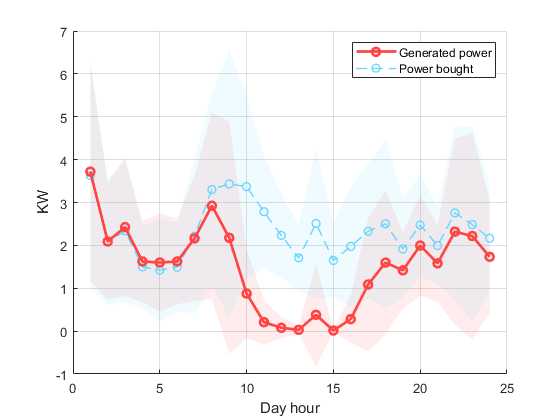

avg_p_up = mean(noncoop.var.p_up, 1);
std_p_up = std(noncoop.var.p_up, 0, 1);

plotter.doublePlot(avg_p_up, std_p_up, avg_DP, std_DP, 2, 1, "-o", "--o", ...
                   colors.retailer, colors.demand, ...
                   "Day hour", "KW", "Power bought", "Demand");

### Power sold

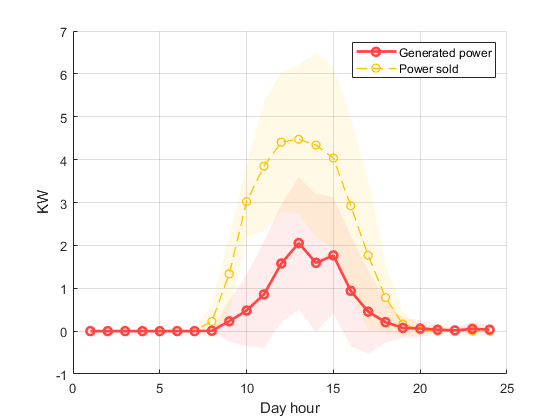

avg_p_down = mean(noncoop.var.p_down, 1);
std_p_down = std(noncoop.var.p_down, 0, 1);

plotter.doublePlot(avg_p_down, std_p_down, avg_PV, std_PV, 2, 1, "-o", "--o", ...
                   colors.retailer, colors.generation, ...
                   "Day hour", "KW", "Power sold", "Generated power");

### Storage and battery state

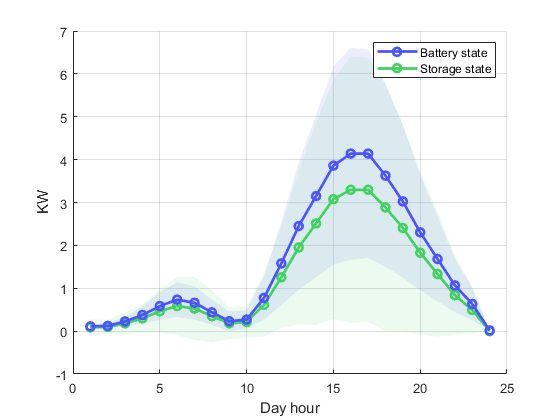

avg_b = mean(noncoop.var.b, 1);
std_b = std(noncoop.var.b, 0, 1);

avg_s = mean(noncoop.var.s, 1);
std_s = std(noncoop.var.s, 0, 1);

plotter.doublePlot(avg_b, std_b, avg_s, std_s, 2, 2, "-o", "-o", ...
                   colors.provider, colors.prosumer, ...
                   "Day hour", "KW", "Battery state", "Storage state");

### Charging and discharging dynamic

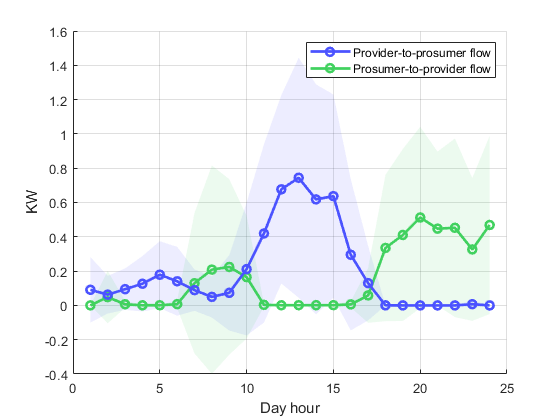

avg_d_down = mean(noncoop.var.d_down, 1);
std_d_down = std(noncoop.var.d_down, 0, 1);

avg_d_up = mean(noncoop.var.d_up, 1);
std_d_up = std(noncoop.var.d_up, 0, 1);

plotter.doublePlot(avg_d_down, std_d_down, avg_d_up, std_d_up, 2, 2, "-o", "-o", ...
                   colors.prosumer, colors.provider, ...
                   "Day hour", "KW", "Prosumer-to-provider flow", "Provider-to-prosumer flow");

### Economy summary

NonCooperativeEconomy = economy(noncoop);
NonCooperativeEconomyTable = economy_table(NonCooperativeEconomy)

NonCooperativeEconomyTable = 3×6 table
                 PowerSoldRevenue    PowerBoughtCosts    PowerStoredCosts    PowerStoredRevenues    EfficiencyCosts    TotalCosts
                 ________________    ________________    ________________    ___________________    _______________    __________

    Prosumers         5.6289              22.391              17.725                    0               158.58           193.06  
    Providers              0                   0                   0               17.833               2.3743          -15.459  
    Retailer          5.6289              22.391                   0                    0                    0           16.762  


CommunityTotalCosts = sum(NonCooperativeEconomy.Prosumers.TotalCosts) + sum(NonCooperativeEconomy.Providers.TotalCosts)

CommunityTotalCosts = 177.6045

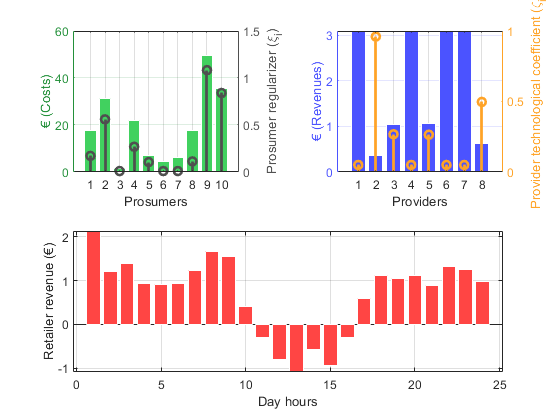


figure;
tiledlayout(2,2);

nexttile;
yyaxis left
ax_pros_cost = gca;
ax_pros_cost.YColor = '#23903a';
bar(NonCooperativeEconomy.Prosumers.TotalCosts, ...
    'EdgeColor', 'w', ...
    'FaceColor', colors.prosumer.hex);
ylabel('€ (Costs)');

yyaxis right
ax_csi = gca;
ax_csi.YColor = '#4F4F4F';
stem(csi, ...
     'Color','#4F4F4F', ...
     'LineWidth', 2);
ylabel('Prosumer regularizer (\xi_i)');
grid on;
xlabel('Prosumers');

nexttile;
yyaxis left
ax_prov_cost = gca;
ax_prov_cost.YColor = colors.provider.rgb;
bar(-NonCooperativeEconomy.Providers.TotalCosts, ...
    'EdgeColor', 'w', ...
    'FaceColor', colors.provider.rgb);
ylabel('€ (Revenues)');

yyaxis right
ax_csi = gca;
ax_csi.YColor = '#FFA326';
stem(zeta, ...
     'Color','#FFA326', ...
     'LineWidth', 2);
ylabel('Provider technological coefficient (\zeta_i)');
grid on; 
xlabel('Providers');
% Retailer revenues
nexttile([1 2]);
bar(NonCooperativeEconomy.Retailer.HourlyRevenues, ...
    'EdgeColor', 'w', ...
    'FaceColor', colors.retailer.hex);
grid on;
ylabel('Retailer revenue (€)');
xlabel('Day hours');

### Saving results 

noncoop.Economy = NonCooperativeEconomy;
save("data/non_cooperative.mat", "noncoop");